## Función para generar animación

function animarRobot3DOF3D(t, q) 
    L = [0 0.145 0.1738];
    L1 = L(1); L2 = L(2); L3 = L(3);
    
    figure;
    grid on;
    hold on;
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    title('Animación del Robot Manipulador 3DOF en 3D');
    axis equal;

    camproj('orthographic'); 
    view(30, 30);            
    
    max_range = L1 + L2 + L3 + 0.2;
    xlim([-max_range, max_range]);
    ylim([-max_range, max_range]);
    zlim([-max_range, max_range]);
    
    plot3(0, 0, 0, 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');

    h_link = plot3(0, 0, 0, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'r');
    
    for k = 1:length(t)
        q1 = q(k,1);
        q2 = q(k,2);
        q3 = q(k,3);
        
        p_0 = [0; 0; 0];

        p_1 = p_0 + [0.072*cos(q1 - 1.0*q2) + 0.072*cos(q1 + q2);
                                0.072*sin(q1 - 1.0*q2) + 0.072*sin(q1 + q2);
                                0.14*sin(q2)];

        p_2 = p_1 + [0.087*cos(q1 + q2 + q3) + 0.072*cos(q1 - 1.0*q2) + 0.072*cos(q1 + q2) + 0.087*cos(q2 - 1.0*q1 + q3);
                             0.087*sin(q1 + q2 + q3) + 0.072*sin(q1 - 1.0*q2) + 0.072*sin(q1 + q2) - 0.087*sin(q2 - 1.0*q1 + q3);
                             0.17*sin(q2 + q3) + 0.14*sin(q2)];
        
        X = [0, p_0(1), p_1(1), p_2(1)];
        Y = [0, p_0(2), p_1(2), p_2(2)];
        Z = [0, p_0(3), p_1(3), p_2(3)];
        
        set(h_link, 'XData', X, 'YData', Y, 'ZData', Z);
        drawnow;
        pause(0.001);
    end
end

## Función con la dinámica del robot

function dxdt = RobotDynamics3dof(~, x, g, params, tau)

    m11 = cos(x(2))^2*params(1) + cos(x(2))*cos(x(2) + x(3))*params(2) + sin(x(2) + x(3))*params(3);
    m22 = params(1) + 2*cos(x(3))*params(2) + params(3);
    m23 = cos(x(3)) * params(2) + params(3);
    m32 = cos(x(3)) * params(2) + params(3);
    m33 = params(3);

    M = [m11 0   0;
        0   m22 m23;
        0   m32 m33];

    c11 = -cos(x(2))*sin(x(2))*x(5)*params(1) - 1/2*(cos(x(2))*sin(x(2) + x(3))*(x(5) + x(6)) + sin(x(2))*cos(x(2) + x(3))*x(5))*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*(x(5) + x(6))*params(3);
    c12 = -cos(x(2))*sin(x(2))*x(4)*params(1) - 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) + sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c13 = -1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c21 = cos(x(2))*sin(x(2))*x(4)*params(1) + 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) - sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c22 = -sin(x(3))*x(6)*params(2);
    c23 = -sin(x(3))*(x(5) + x(6))*params(2);
    c31 = 1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) - cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c32 = sin(x(5))*params(2);
    c33 = 0;

    C = [c11 c12 c13;
         c21 c22 c23;
         c31 c32 c33];

    d1=params(4)*x(4);
    d2=params(5)*x(5);
    d3=params(6)*x(6);

    D=[d1; d2; d3];

    g2 = g*(cos(x(2))*params(7) + cos(x(2) + x(3))*params(8));
    g3 = g*cos(x(2) + x(3))*params(8);

    g = [0;
        g2;
        g3];
    
    q_dot = [x(4); x(5); x(6)];

    q_ddot = inv(M) * (tau - C * q_dot - D - g);

    dxdt = [q_dot;
        q_ddot];
end

## Cinemática Directa

syms q1 q2 q3

H01 = Transform.rotZ(q1)*Transform.transZ(0)*Transform.transX(0)*Transform.rotX(pi/2);
H12 = Transform.rotZ(q2)*Transform.transZ(0)*Transform.transX(0.145)*Transform.rotX(0);
H23 = Transform.rotZ(q3)*Transform.transZ(0)*Transform.transX(0.1738)*Transform.rotX(0);

vpa(simplify(H01),2)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -6.1e-17\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 6.1e-17\,\cos\left(q_{1}\right) & -1.0\,\cos\left(q_{1}\right) & 0\\ 0 & 1.0 & 6.1e-17 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(simplify(H01*H12),2)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 0.5\,\sigma_{3}+\sigma_{4} & 0.5\,\sigma_{1}-\sigma_{2} & \sin\left(q_{1}\right) & 0.072\,\sigma_{3}+0.072\,\cos\left(q_{1}+q_{2}\right)\\ 0.5\,\sigma_{1}+\sigma_{2} & \sigma_{4}-0.5\,\sigma_{3} & -1.0\,\cos\left(q_{1}\right) & 0.072\,\sigma_{1}+0.072\,\sin\left(q_{1}+q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 6.1e-17 & 0.14\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}-1.0\,q_{2}\right)\\ \sigma_{2}=0.5\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\cos\left(q_{1}-1.0\,q_{2}\right)\\ \sigma_{4}=0.5\,\cos\left(q_{1}+q_{2}\right) \end{array}$$

vpa(simplify(H01*H12*H23),2)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 0.5\,\sigma_{2}+0.5\,\cos\left(\sigma_{3}\right) & -0.5\,\sigma_{1}-0.5\,\sin\left(\sigma_{3}\right) & \sin\left(q_{1}\right) & 0.087\,\sigma_{2}+0.072\,\cos\left(q_{1}-1.0\,q_{2}\right)+0.072\,\cos\left(q_{1}+q_{2}\right)+0.087\,\cos\left(\sigma_{3}\right)\\ 0.5\,\sigma_{1}-0.5\,\sin\left(\sigma_{3}\right) & 0.5\,\sigma_{2}-0.5\,\cos\left(\sigma_{3}\right) & -1.0\,\cos\left(q_{1}\right) & 0.087\,\sigma_{1}+0.072\,\sin\left(q_{1}-1.0\,q_{2}\right)+0.072\,\sin\left(q_{1}+q_{2}\right)-0.087\,\sin\left(\sigma_{3}\right)\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 6.1e-17 & 0.17\,\sin\left(q_{2}+q_{3}\right)+0.14\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{3}=q_{2}-1.0\,q_{1}+q_{3} \end{array}$$

## Solución de la ecuación diferencial

format long

params = [  0.00349359
            0.00246677
            0.00333632
            0.00076823
            0.03526735
            0.00744473
            0.00449158
            0.01701218
          ];

x0 = [pi/4; 0; 0; 0; 0; 0];
tspan = 0:0.01:5;
tau = 0;
g = 9.81;

[t, x] = ode45(@(t,x) RobotDynamics3dof(t, x, g, params, tau), tspan, x0);

## Gráficas de articulaciones

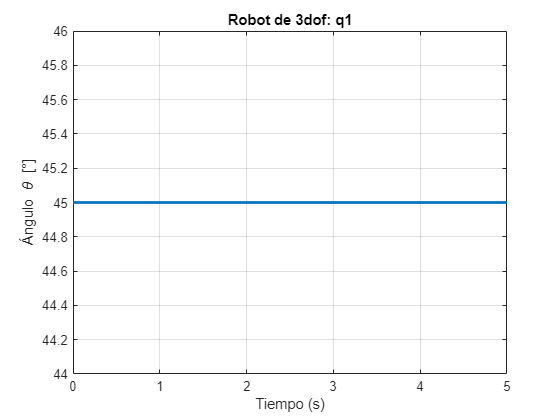

figure;
plot(t, x(:,1)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q1');
grid on;

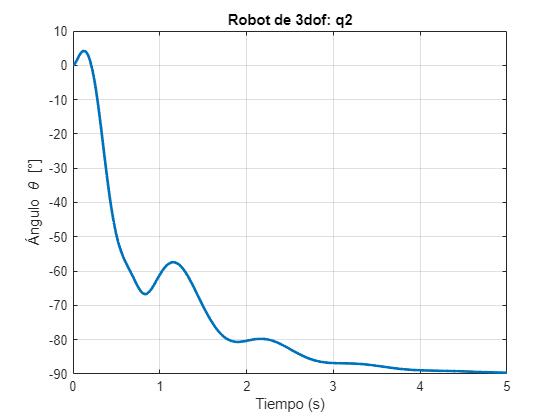


figure;
plot(t, x(:,2)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q2');
grid on;

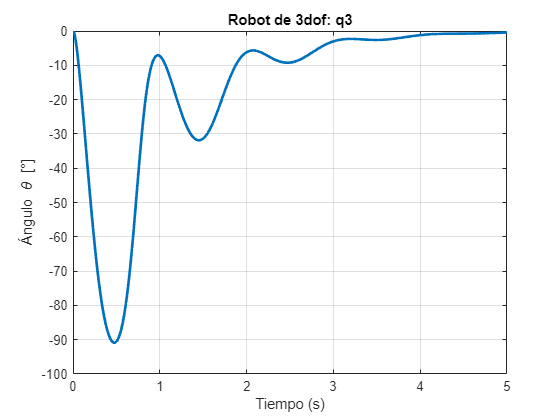


figure;
plot(t, x(:,3)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q3');
grid on;

## Animación

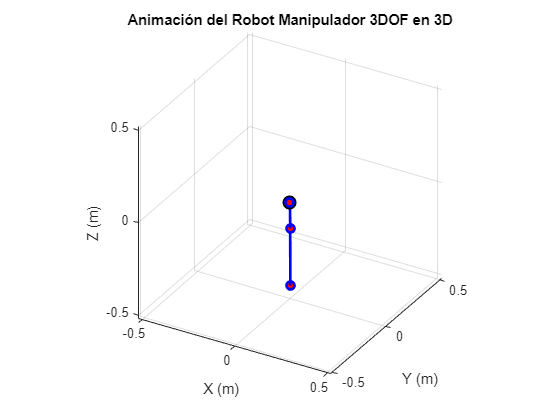

animarRobot3DOF3D(t, x);